mean(sig,"all")

ans = -32768

Fs =500

Fs = 500

fb = cwtfilterbank('SignalLength',5000,'SamplingFrequency',Fs,'VoicesPerOctave',12);
sig = data(1160,7 ,1:5000);
sig = sig(:)

sig =       -32768
      -32768
      -32768
      -32768
      -32768
      -32768
      -32768
      -32768
      -32768
      -32768


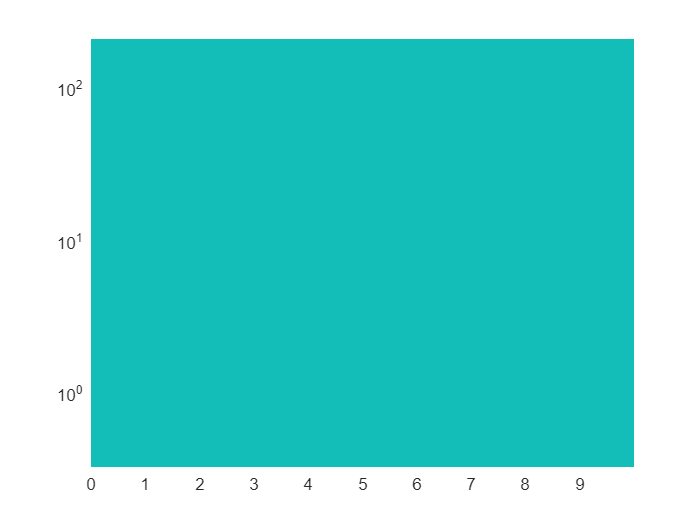

[cfs,frq] = wt(fb,sig);
t = (0:4999)/Fs;figure;pcolor(t,frq,abs(cfs))
set(gca,'yscale','log');
shading interp;
axis tight;

Fs =500;
fb = cwtfilterbank('SignalLength',5000,'SamplingFrequency',Fs,'VoicesPerOctave',12);
for sample = 1:1698
    clf
    t = (0:4999)/Fs;
    ha = tight_subplot(3,4,[.005 .005],[.005 .005],[.005 .005]);
    for channel = 1:12
        sig = data(sample,channel,1:5000);
        sig = sig(:);
        [cfs,frq] = wt(fb,sig);
        axes(ha(channel)); 
        pcolor(t,frq,abs(cfs));
        set(gca,'yscale','log');
        set(gca,'xtick',[]);
        set(gca,'ytick',[]);
        shading interp;
        axis tight;
    end
    set(gcf,'position',[0,0,1200,1200])
    saveas(gcf, ['./PNG_Power/',num2str(sample),'.jpg'])
end